I=1; %Inhibitory Auditory Neuron
% A1
newA1sp=[ASpike(:,1:1050); AVSpike(:,1:1050); AMSpike(:,1:1050)];
[A1Tlen,~]=size(newA1sp);
sd=20;
A1fr = 1000*smooth(newA1sp, sd);
A1mfr= mean(A1fr,1);
A1sdfr=std(A1fr,[],1);
A1sefr=A1sdfr/sqrt(A1Tlen);
t=[1:length(newA1sp)];

e1=A1mfr-A1sefr;
e2=A1mfr+A1sefr;

h1=subplot(2,1,1);
L(1)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'r','EdgeColor','r','FaceColor','r');
hold on;
plot(t,A1mfr,'Color','k','LineStyle','-')

% A4
newA4sp=[ASpike(:,t2-450:end)];
[A4Tlen,~]=size(newA4sp);
sd=20;
A4fr = 1000*smooth(newA4sp, sd);
A4mfr= mean(A4fr,1);
A4sdfr=std(A4fr,[],1);
A4sefr=A4sdfr/sqrt(A4Tlen);
t=[1:length(newA4sp)];

e1=A4mfr-A4sefr;
e2=A4mfr+A4sefr;
% 
L(2)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'y','EdgeColor','y','FaceColor','y');
hold on;
plot(t,A4mfr,'Color','k','LineStyle','-')
xlabel('Time (ms)')
ylabel('firing rate (spk/s)')
xlim([0 1000])
legend(L,{'A1','A4'});

% 
Q1=1;
Q2=851;
var1=A1sdfr(Q1:Q2).^2;
var2=A4sdfr(Q1:Q2).^2;
var3=A1sefr(Q1:Q2).^2;
var4=A4sefr(Q1:Q2).^2;
rdif=A1mfr(Q1:Q2)-A4mfr(Q1:Q2);
Nr=length(rdif);
SEdif=sqrt(var3+var4);
e1=rdif-SEdif;
e2=rdif+SEdif;
t=[Q1:Q2];
h2=subplot(2,1,2);
fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'g','EdgeColor','g','FaceColor','g')
hold on 
plot(t,rdif,'Color','k','LineStyle','-')
xlabel('Time (ms)')
ylabel('firing rate (spk/s)')
xlim([0 1000])
%Part 5b
[AWMItse,AWMPtse] = detsign(rdif,SEdif,Q1,Q2,1);

No Visual Within Modal Potentiation


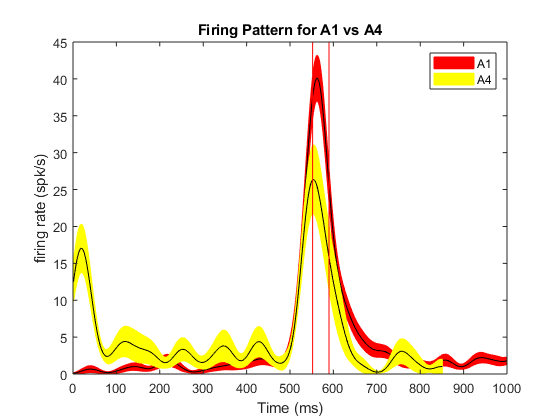

o=1; p=2;
q=1; 
if I==1
    AWMItse1=AWMItse(o);
    AWMItse2=AWMItse(p);
    AWMPtse1=AWMPtse(q);
    AWMPtse2=AWMPtse(q);
else
    AWMItse1=AWMItse(q);
    AWMItse2=AWMItse(q);
    AWMPtse1=AWMPtse(o);
    AWMPtse2=AWMPtse(p);
end
axes(h1)
title({'';'Firing Pattern for A1 vs A4'})
if I==1
    line([AWMItse1 AWMItse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMItse2 AWMItse2],ylim,'Color','r','HandleVisibility','off');
else
    line([AWMPtse1 AWMPtse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMPtse2 AWMPtse2],ylim,'Color','r','HandleVisibility','off');
end

axes(h2)
title({'';'Difference between A1 and A4'})
if I==1
    line([AWMItse1 AWMItse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMItse2 AWMItse2],ylim,'Color','r','HandleVisibility','off');
else
    line([AWMPtse1 AWMPtse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMPtse2 AWMPtse2],ylim,'Color','r','HandleVisibility','off');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% V1
newV1sp=[VSpike(:,1:1050); VASpike(:,1:1050); VMSpike(:,1:1050)];
[V1Tlen,~]=size(newV1sp);
sd=20;
V1fr = 1000*smooth(newV1sp, sd);
V1mfr= mean(V1fr,1);
V1sdfr=std(V1fr,[],1);
V1sefr=V1sdfr/sqrt(V1Tlen);
t=[1:length(newV1sp)];

e1=V1mfr-V1sefr;
e2=V1mfr+V1sefr;
figure
h1=subplot(2,1,1);
L(1)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'b','EdgeColor','b','FaceColor','b');
hold on;
plot(t,V1mfr,'Color','k','LineStyle','-')

% AV4
newAV4sp=[AVSpike(:,t2-450:end)];
[AV4Tlen,~]=size(newAV4sp);
AV4fr = 1000*smooth(newAV4sp, sd);
AV4mfr= mean(AV4fr,1);
AV4sdfr=std(AV4fr,[],1);
AV4sefr=AV4sdfr/sqrt(AV4Tlen);
t=[1:length(newAV4sp)];
e1=AV4mfr-AV4sefr;
e2=AV4mfr+AV4sefr;
L(2)=fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'y','EdgeColor','y','FaceColor','y');
plot(t,AV4mfr,'Color','k','LineStyle','-')
xlim([0 1000])
xlabel('Time (ms)')
ylabel('firing rate (spk/s)')
legend(L,{'V1','AV4'});

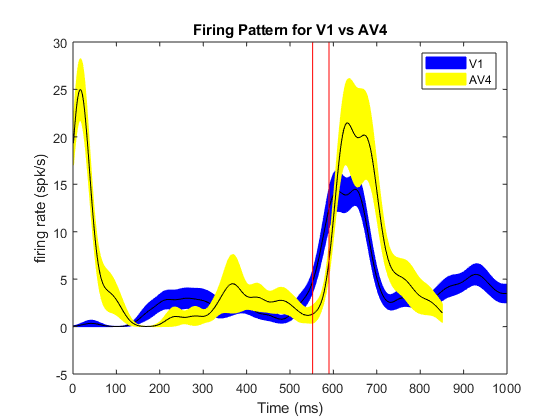

% 
Q1=1;
Q2=851;
var1=V1sdfr(Q1:Q2).^2;
var2=AV4sdfr(Q1:Q2).^2;
var3=V1sefr(Q1:Q2).^2;
var4=AV4sefr(Q1:Q2).^2;
rdif=V1mfr(Q1:Q2)-AV4mfr(Q1:Q2);
Nr=length(rdif);
SEdif=sqrt(var3+var4);
e1=rdif-SEdif;
e2=rdif+SEdif;
t=[Q1:Q2];
h2=subplot(2,1,2);
fill([t t(end:-1:1)],[e1,e2(end:-1:1)],'g','EdgeColor','g','FaceColor','g')
hold on 
plot(t,rdif,'Color','k','LineStyle','-')
xlabel('Time (ms)')
ylabel('firing rate (spk/s)')
xlim([0 1000])
%Part 5b
[AIVtse,APVtse] = detsign(rdif,SEdif,Q1,Q2,1);
inheffecton=AWMItse1-525;
inheffectoff=AWMItse2-525;

axes(h1)
title({'';'Firing Pattern for V1 vs AV4'})
if I==1
    line([AWMItse1 AWMItse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMItse2 AWMItse2],ylim,'Color','r','HandleVisibility','off');
else
    line([AWMPtse1 AWMPtse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMPtse2 AWMPtse2],ylim,'Color','r','HandleVisibility','off');
end

axes(h2)
title({'';'Difference between V1 and AV4'})
if I==1
    line([AWMItse1 AWMItse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMItse2 AWMItse2],ylim,'Color','r','HandleVisibility','off');
else
    line([AWMPtse1 AWMPtse1],ylim,'Color','r','HandleVisibility','off');
    line([AWMPtse2 AWMPtse2],ylim,'Color','r','HandleVisibility','off');
end